Suppose wee have a digital signal. Then it is in the form of a discrete sequence of 0s and 1s.

eg: [0 1 1 0 1 0 0 0 1] etc

Electrically, it exists as pulses. a high voltage, say 1V for 1 and 0V for 0.

Each pulse lasts for a finite duration. So let us represent a sequence as an electric signal.

Once again, you are welcome to implement all these using loops, but these vectorised forms are quicker due to internal parallelizations in MATLAB.

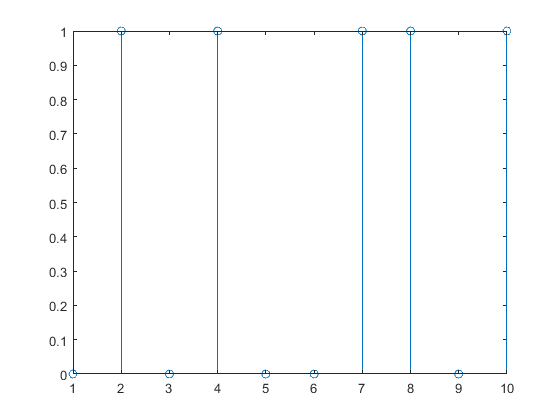

ta = 0.1;            % Pulse duration is 0.1  s
m  = [0 1 0 1 0 0 1 1 0 1];  % Our digital sequence
stem(m);

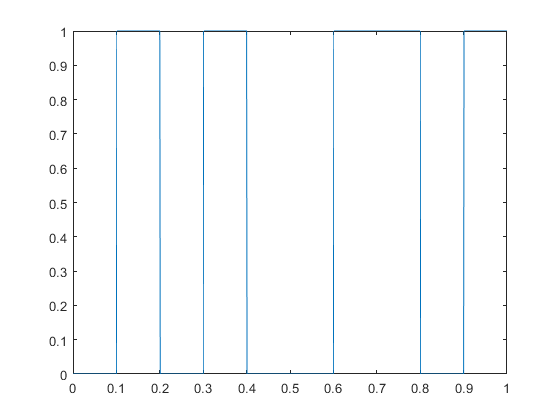


% Let us create a vector of time values:
dt = 0.001;           % Our Sampling Period

% The signal lasts from 0 to ta*(sequence size) seconds.
t = dt:dt:ta*size(m, 2);

% Now all time points, t from k*ta to (k+1)*ta must have the value m(k+1) thus,
% t/ta lies from k to k+1. hence, ceil(t/ta) = k+1 if we choose to sacrifice single
% value at t = k*ta.
s = m(ceil(t/ta));

plot(t, s);

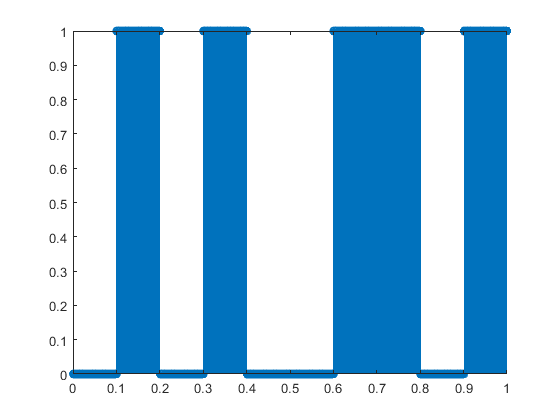

% For better visualisation:
stem(t, s);

Now, let us reconstruct out original message from the given electrical signal. To do that we need to only sample values from each pulse. Let us take the middle value of each pulse.

% starting from the first sample at ta/2 we take a gap of ta until the end.
sampling_times = ta/2:ta:ta*size(m, 2);

% in actual vector s, the time 't' corresponds to the index t/dt.
m_reconstructed = s(floor(sampling_times/dt));

stem(m_reconstructed);

I recommend you to practice these manually in your normal environment. You can also make a matlab script file (recommended) to do so.